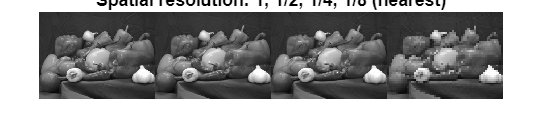

I = imread('peppers.png');
G = rgb2gray(I);
G = im2uint8(G);

s = [1 0.5 0.25 0.125];
S = cell(1,numel(s));
for k = 1:numel(s)
    J = imresize(G,s(k),'nearest');
    J = imresize(J,size(G),'nearest');
    S{k} = J;
end
figure('Name','Spatial resolution');
montage(S,'Size',[1 numel(S)]);
title('Spatial resolution: 1, 1/2, 1/4, 1/8 (nearest)');

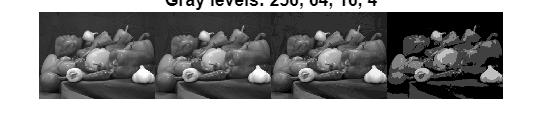


levels = [256 64 16 4];
Q = cell(1,numel(levels));
for k = 1:numel(levels)
    L = levels(k);
    step = 256/L;
    J = uint8(floor(double(G)/step)*step);
    Q{k} = J;
end
figure('Name','Gray-level resolution');
montage(Q,'Size',[1 numel(levels)]);
title('Gray levels: 256, 64, 16, 4');

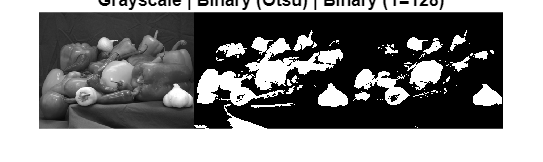


T = graythresh(G);
BW_otsu = imbinarize(G,T);
BW_128 = G >= 128;

figure('Name','Binary conversion');
montage({G,BW_otsu,BW_128},'Size',[1 3]);
title('Grayscale | Binary (Otsu) | Binary (T=128)');


ref = double(G);

mseS = zeros(1,numel(S));
psnrS = zeros(1,numel(S));
ssimS = zeros(1,numel(S));
for k = 1:numel(S)
    X = double(S{k});
    mseS(k) = mean((ref(:)-X(:)).^2);
    psnrS(k) = 10*log10(255^2/mseS(k));
    ssimS(k) = ssim(uint8(S{k}),G);
end

mseQ = zeros(1,numel(Q));
psnrQ = zeros(1,numel(Q));
ssimQ = zeros(1,numel(Q));
for k = 1:numel(Q)
    X = double(Q{k});
    mseQ(k) = mean((ref(:)-X(:)).^2);
    psnrQ(k) = 10*log10(255^2/mseQ(k));
    ssimQ(k) = ssim(uint8(Q{k}),G);
end

BW_otsu_255 = uint8(BW_otsu)*255;
BW_128_255  = uint8(BW_128)*255;

bin_mse_otsu = mean((ref(:)-double(BW_otsu_255(:))).^2);
bin_psnr_otsu = 10*log10(255^2/bin_mse_otsu);
bin_ssim_otsu = ssim(BW_otsu_255,G);

bin_mse_128 = mean((ref(:)-double(BW_128_255(:))).^2);
bin_psnr_128 = 10*log10(255^2/bin_mse_128);
bin_ssim_128 = ssim(BW_128_255,G);

disp('Spatial resolution metrics (scale, MSE, PSNR, SSIM):')

Spatial resolution metrics (scale, MSE, PSNR, SSIM):


disp([s(:) mseS(:) psnrS(:) ssimS(:)])

    1.0000         0       Inf    1.0000
    0.5000   48.4973   31.2736    0.9206
    0.2500  104.5494   27.9376    0.8387
    0.1250  264.5119   23.9064    0.7256




disp('Gray-level resolution metrics (levels, MSE, PSNR, SSIM):')

Gray-level resolution metrics (levels, MSE, PSNR, SSIM):


disp([levels(:) mseQ(:) psnrQ(:) ssimQ(:)])

   1.0e+03 *

    0.2560         0       Inf    0.0010
    0.0640    0.0035    0.0427    0.0010
    0.0160    0.0758    0.0293    0.0009
    0.0040    1.8009    0.0156    0.0003




disp('Binary conversion metrics:')

Binary conversion metrics:


disp(table(["Otsu";"T=128"],[bin_mse_otsu;bin_mse_128],[bin_psnr_otsu;bin_psnr_128],[bin_ssim_otsu;bin_ssim_128], ...
    'VariableNames',{'Method','MSE','PSNR','SSIM'}))

    Method      MSE       PSNR       SSIM  
    _______    ______    ______    ________

    "Otsu"     6309.1    10.131     0.13792
    "T=128"    5478.2    10.744    0.086869

